# Analysis of social, multi-flavor experiment on 2/12/2024

## Data import

clear all

#### Root directory

rootdir = 'Z:\users\Tatsumi\data\MultiReward\multibat\240212';
ephys_rootdir = 'Z:\users\Tatsumi\data\MultiReward\multibat\240212\ephys\20240212_081836.rec'; % the root directory of all merged rec files
cd(rootdir)

### Subdirectory

% preprocessing
% run PreprocessAllEphys.m
% run PreprocessBhvData.m

% output directory
analysis_dirpath     =   fullfile(rootdir,'analysis');
if isempty(dir(analysis_dirpath)); mkdir(analysis_dirpath); end
% Figure
fig_dirpath    =   fullfile(analysis_dirpath,'figure');
if isempty(dir(fig_dirpath)); mkdir(fig_dirpath); end

### Experiment info

mtData.rec_date = '240212'; % recording date
mtData.rec_type = 'untethered'; % recording type
mtData.exp_type = 'social'; % experiment type
mtData.reward_type = 'multi-flavor'; % reward type

% Bat subjects
mtData.bname = {"14447","11827","29924","14406","14561","14633","14662","14531","71050","9776"}; % in order of serial number list
mtData.bname_ephys = {'14633','14662'}; % ephys bat

% reward
mtData.reward_list = {"banana","pear","grape","melon"};
mtData.reward_session = [1,2,0,0; 2,1,0,0];
save(fullfile(rootdir,'analysis','exp_info.mat'),'mtData')

### Preprocess and load behavioral data

[BhvData, AnalogData] = PreprocessBhvData(rootdir);

Extracted data are found in the directory.
Behavior data are found in the directory.
Analog signal data are found.


Final MinPeakDistance was 0.6 
120 peaks were detected. 
1 artifacts were detected. It matches with the number of sessions. 
All rewarding landings were recorded and detected.


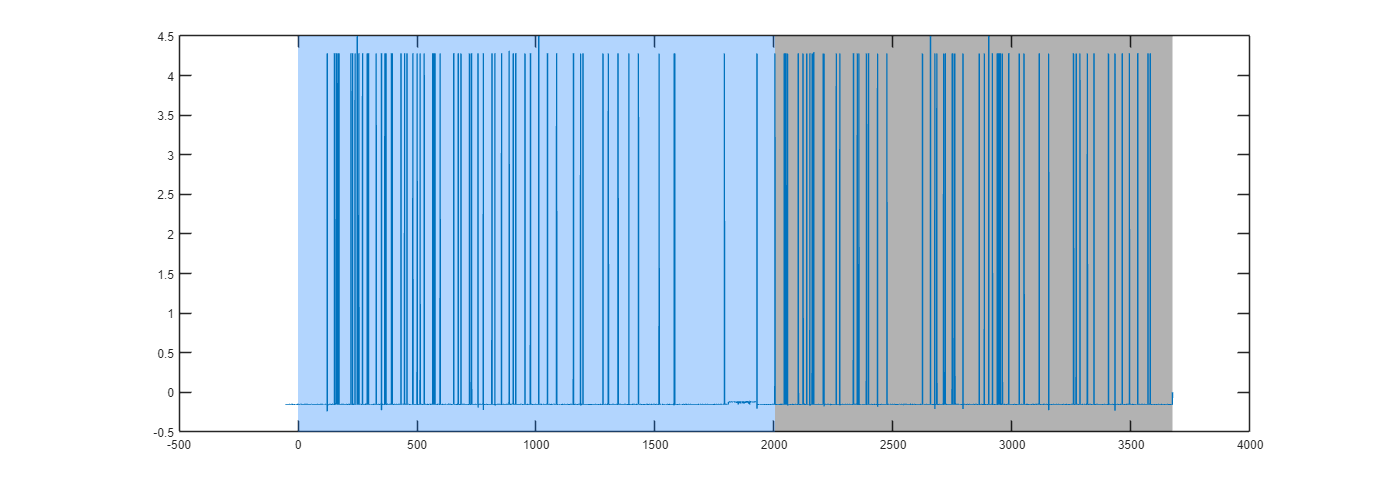

RewardData = PreprocessRewardData(rootdir);

## Feature engineering

### Detect takeoff/landings based on the cdp data

Extract the start/end timings and the position of all the landings/flights. The extracted information is saved into `Landings/Flights`

% % All landings
% Landings = extractLandings(BhvData,RewardData,'include','all');
% for bb = 1:length(Landings)
%     n_land = Landings(bb).n_land;
%     fprintf('%dth bat: %d landing were detected. \n',bb, n_land)
% end
% 
% % feeder landings
% Landings_fd = extractLandings(BhvData,RewardData,'include','feeder');
% for bb = 1:length(Landings_fd)
%     n_land = Landings_fd(bb).n_land;
%     fprintf('%dth bat: %d landing were detected. \n',bb, n_land)
% end

#### Clustering the flight trajectories

Landings = extractLandings(BhvData,RewardData,mtData,'include','all');
% Hierarchical clustering of trajectories
% hc = TrajClusteringHC(Landings,'cutoff',1,'minpts',2,'n_smp',50,'n_dim',3);
% FigDir = fullfile(pwd,'analysis','figure','ClusteredTrajectory_HC');
% PlotClusteredTrajectory(TrjCluster,'FigDir',FigDir)

% DBSCAN clustering of trajectories
TrjCluster = TrajClusteringDBSCAN(Landings,'minpts',2,'n_smp',100,'n_dim',3);

8 clusters for bat 1 are detected. 
2 clusters for bat 2 are detected. 
6 clusters for bat 3 are detected. 
9 clusters for bat 4 are detected. 
4 clusters for bat 5 are detected. 
11 clusters for bat 6 are detected. 
7 clusters for bat 7 are detected. 
8 clusters for bat 8 are detected. 
2 clusters for bat 9 are detected. 
6 clusters for bat 10 are detected. 


FigDir = fullfile(rootdir,'analysis','figure','ClusteredTrajectory_DBSCAN');
PlotClusteredTrajectory(TrjCluster,'FigDir',FigDir)

for bb = 1:n_tags
    mean(Landings_fd(bb).num_close_oth)
    
    num_oth_on_feeder = Landings_fd(bb).num_oth_on_feeder;

    landed_fd = Landings_fd(bb).closest_feeder(:,2);
    nonlanded_fd = -1 * landed_fd + 3; % switch the values
    num_oth_same_fd = zeros(length(landed_fd),1);
    num_oth_diff_fd = zeros(length(nonlanded_fd),1);
    
    for ll = 1:length(landed_fd)
        num_oth_same_fd(ll) = num_oth_on_feeder(ll,landed_fd(ll));
        num_oth_diff_fd(ll) = num_oth_on_feeder(ll,nonlanded_fd(ll));
    end
    [mean(num_oth_same_fd), mean(num_oth_diff_fd)]

    cnt_oth_same_fd = zeros(length(landed_fd),1);
    cnt_oth_diff_fd = zeros(length(nonlanded_fd),1);
    
    for ll = 1:length(landed_fd)
        if num_oth_on_feeder(ll,landed_fd(ll)) ~= 0
               cnt_oth_same_fd(ll) = 1;
        end
        if num_oth_on_feeder(ll,nonlanded_fd(ll)) ~= 0
            cnt_oth_diff_fd(ll) = 1;
        end
    end
    [mean(cnt_oth_same_fd), mean(cnt_oth_diff_fd)]


end

ans = 0.4000

ans =     0.4000    0.6000


ans =     0.2000    0.6000


ans = NaN

ans =    NaN   NaN


ans =    NaN   NaN


ans = 0.1538

ans =     0.1538    0.7692


ans =     0.1538    0.6154


ans = 0.3902

ans =     0.3902    0.3902


ans =     0.3659    0.3902


ans = 0.6667

ans =     0.6667    0.6667


ans =     0.6667    0.6667


ans = 0.3548

ans =     0.3548    0.4839


ans =     0.2903    0.4839


ans = 0.6667

ans =     0.6667    0.8889


ans =     0.6667    0.7778


ans = 0.3125

ans =     0.3125    0.2917


ans =     0.2500    0.2708


ans = NaN

ans =    NaN   NaN


ans =    NaN   NaN


ans = 0.4667

ans =     0.4667    0.6667


ans =     0.3333    0.4667


### Feeder/reward preference based on the cdp data

#### Feeder preference

Compute preference for feeder and/or reward.

Feeder/reward preference index (PI), defined as (|F1-F2|/|F1+F2|) where F1 or F2 is the counts of landings on the feeder 1 or feeder 2.

The range is -1 < PI < 1. The larger PI means that the bat prefers to the feeder 1, while the lower PI means that the bat does the feeder 2.

PI = 0 means that there is no preference.

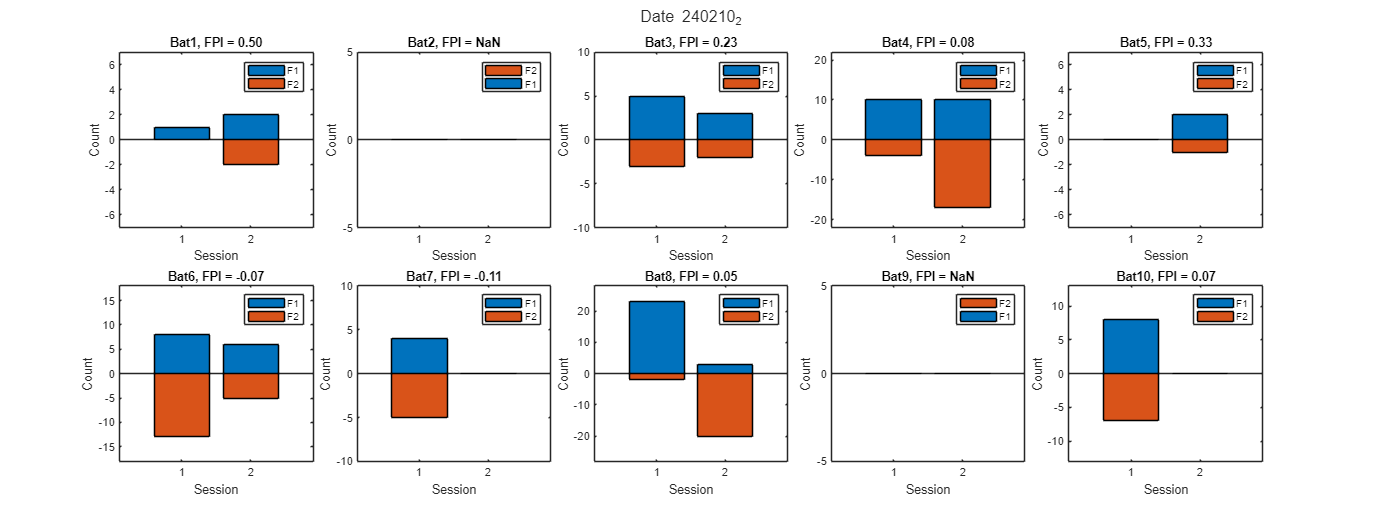

% Load data
Landings_fd = extractLandings(BhvData,RewardData,mtData,'include','feeder'); % landings
n_session = RewardData.n_session; % number of sessions
n_bats = length(Landings_fd); % number of bats
% n_feeder = 2; % number of feeders

%%% FIGURE: feeder preference
fig = figure;
fontsize(fig, 24, "points")
set(fig, 'units','normalized','Position',[0.2 0.2 0.6 0.4]);
tl = tiledlayout(2,5,"TileSpacing",'compact');
title(tl,sprintf('Date %s',mtData.rec_date))
for bb = 1:n_bats   
    % Feeder preference
    feeder_pref = Landings_fd(bb).FP; % feeder preference counts
    feeder_pref(:,2) = feeder_pref(:,2)*-1; % convert the feeder 2 to negative for plot
    feeder_pref_index = Landings_fd(bb).FPI; % feeder preference index
    
    max_cnt = max(max(abs(feeder_pref)));

    % FIGURE
    nexttile
    bar(categorical(1:n_session),feeder_pref,'stacked')
    title(sprintf('Bat%s, FPI = %.2f',num2str(bb),mean(feeder_pref_index,'omitnan')))
    xlabel('Session'); ylabel('Count'); legend({"F1","F2"})
    ylim([-1*(max_cnt+5),max_cnt+5])
end
% Save figure
FigDir = fullfile(fig_dirpath,'feeder_preference');
if isempty(dir(FigDir)); mkdir(FigDir); end
saveas(fig,fullfile(FigDir,'Feeder_preference_cdp.png'))

Cumulative plot for the feeder preference

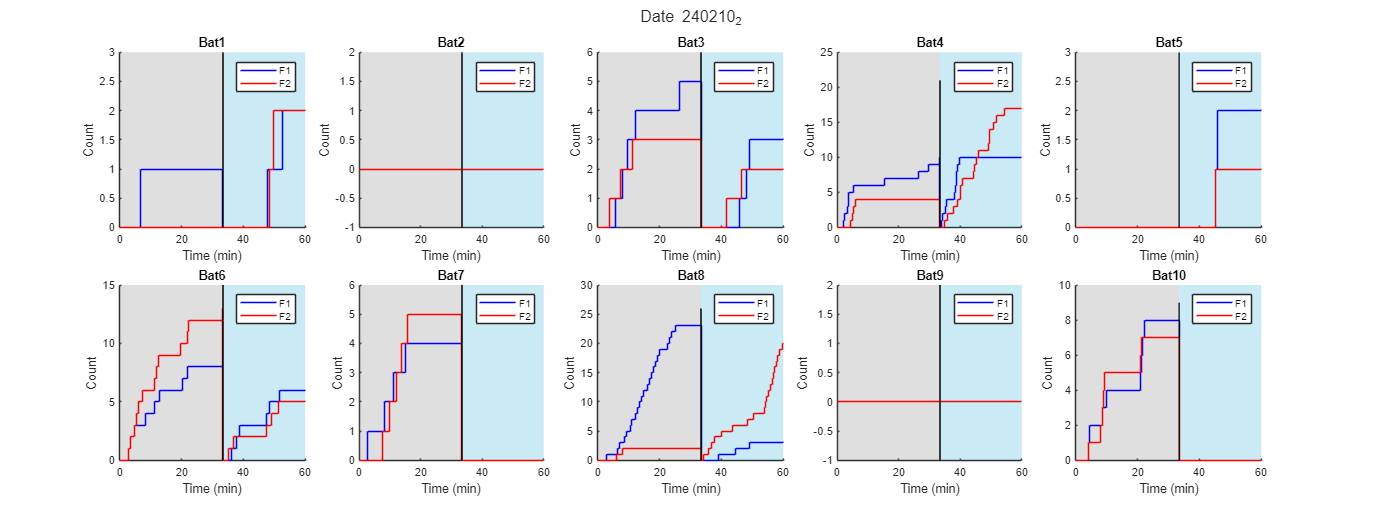

% Landings_fd = extractLandings(BhvData,RewardData,'include','feeder'); % landings
t_session = RewardData.t_session_sec; % time of the start of sessions in sec
t = BhvData.t; % timestamps for behavior data
n_session = RewardData.n_session; % number of sessions
n_bats = length(mtData.bname); % number of bats

%%% FIGURE: cumulative plot of feeder landings
fig = figure;
fontsize(fig, 24, "points")
set(fig, 'units','normalized','Position',[0.2 0.2 0.6 0.4]);
tl = tiledlayout(2,5,"TileSpacing",'compact');
title(tl, sprintf('Date %s',mtData.rec_date))
fig_clr = {'b','r'};
for bb = 1:n_bats
    nexttile
    hold on
    for ff = 1:2 % number of active feeder
        t_rw_cum_sec = Landings_fd(bb).feeder_preference(ff).t_reward_cum_sec; % timings of cumulative rewards
        reward_cum = Landings_fd(bb).feeder_preference(ff).reward_cum; % cumulative rewards
        t_rw_cum_min = t_rw_cum_sec / 60; % convert to minutes
        
    
        stairs(t_rw_cum_min,reward_cum,'Color',fig_clr{ff})
    end
    title(sprintf('Bat%s',num2str(bb)))
    xlabel('Time (min)')
    ylabel('Count')
    
    % Draw the boundary of session
    y_lim = ylim;
    for ss = 2:n_session
        plot([t_session(ss)/60,t_session(ss)/60],[y_lim(1),y_lim(2)+1],'k')
    end

    for session = 1:n_session
        if mod(session,2) == 0
            if session ~= n_session
                xregion(t_session(session)/60,t_session(session+1)/60,'FaceColor',[80,190,225]/255)
            else
                xregion(t_session(session)/60,t(end)/60,'FaceColor',[80,190,225]/255)
            end
        else
            if session ~= n_session
                xregion(t_session(session)/60,t_session(session+1)/60,'FaceColor',[150,150,150]/255)
            else
                xregion(t_session(session)/60,t(end)/60,'FaceColor',[150,150,150]/255)
            end
        end
    end

    hold off

    f=get(gca,'Children');
    legend([f(length(f)),f(length(f)-1)],'F1','F2')
end

% Figure directory
FigDir = fullfile(fig_dirpath,'feeder_preference');
if isempty(dir(FigDir))
    mkdir(FigDir)
end
saveas(gcf,fullfile(FigDir,'Cumulative_feeder_preference_cdp.png'))

Same for reward preference.

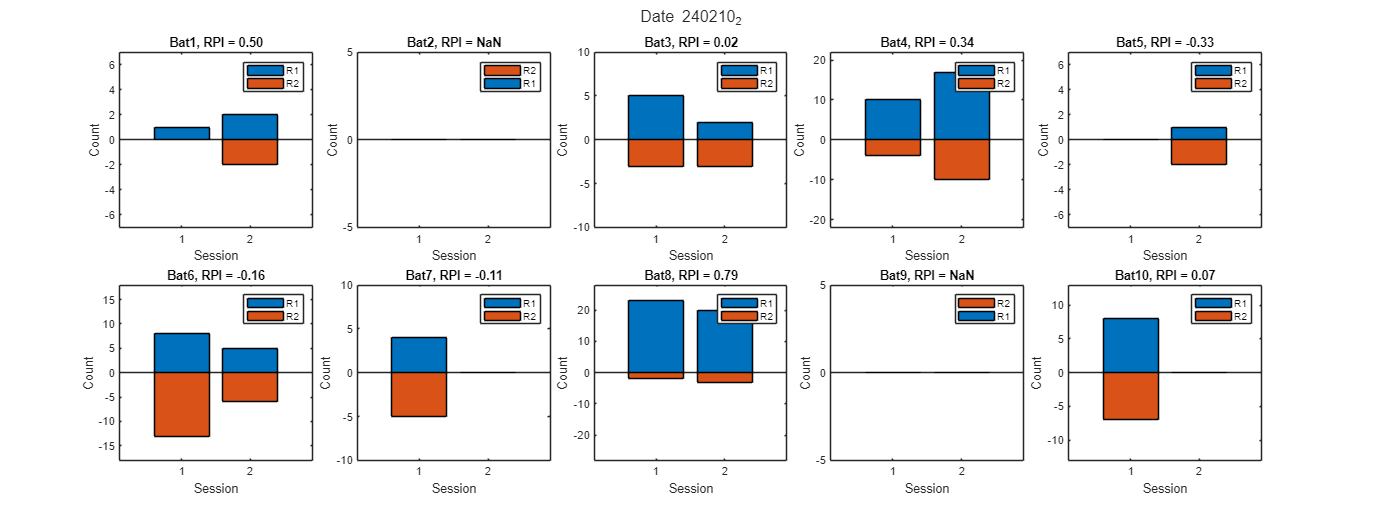

% Load data
Landings_fd = extractLandings(BhvData,RewardData,mtData,'include','feeder'); % landings
n_session = RewardData.n_session; % number of sessions
n_bats = length(mtData.bname); % number of bats
% n_reward = 2; % number of types of reward

%%% FIGURE: feeder preference
fig = figure;
fontsize(fig, 24, "points")
set(fig, 'units','normalized','Position',[0.2 0.2 0.6 0.4]);
tl = tiledlayout(2,5,"TileSpacing",'compact');
title(tl, sprintf('Date %s',mtData.rec_date))
for bb = 1:n_bats   
    % Reward preference
    reward_pref = Landings_fd(bb).RP; % reward preference counts
    reward_pref(:,2) = reward_pref(:,2)*-1; % convert the 2nd reward for plot
    reward_pref_index = Landings_fd(bb).RPI; % reward preference counts

    max_cnt = max(max(abs(reward_pref)));

    % FIGURE
    nexttile
    bar(categorical(1:n_session),reward_pref,'stacked')
    title(sprintf('Bat%s, RPI = %.2f',num2str(bb),mean(reward_pref_index,'omitnan')))
    xlabel('Session')
    ylabel('Count')
    legend({"R1","R2"})
    ylim([-1*(max_cnt+5),max_cnt+5])
end

% Save figure
FigDir = fullfile(fig_dirpath,'feeder_preference');
if isempty(dir(FigDir))
    mkdir(FigDir)
end
saveas(fig,fullfile(FigDir,'Reward_preference_cdp.jpg'))

Cumulative plot for the reward preferences

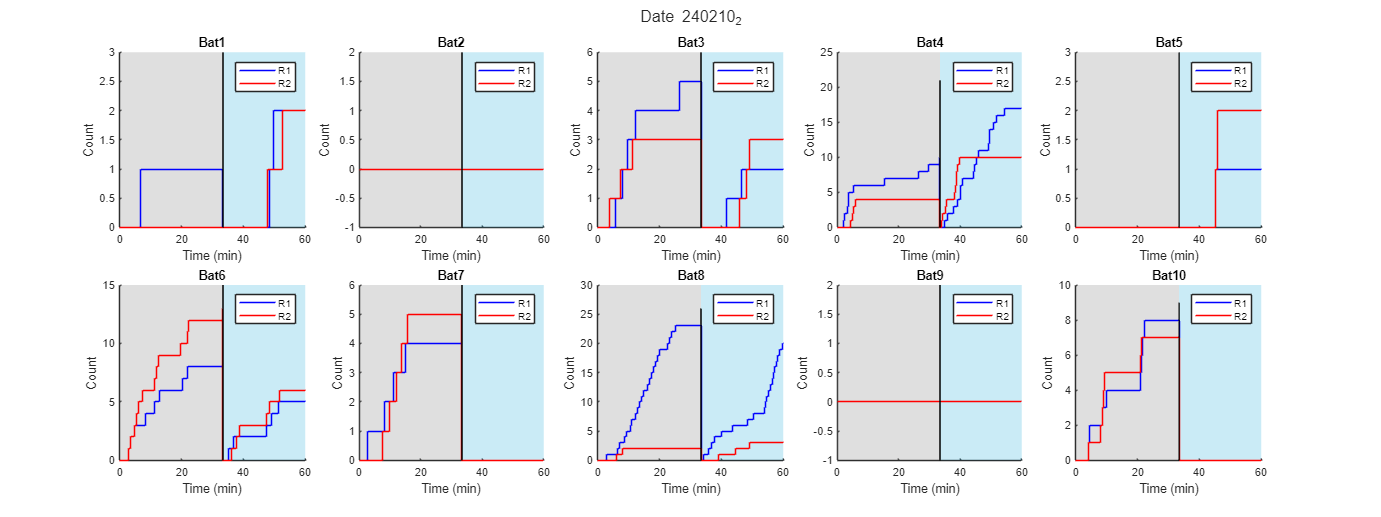

% Landings_fd = extractLandings(BhvData,RewardData,mtData,'include','feeder'); % landings
t_session = RewardData.t_session_sec; % time of the start of sessions in sec
t = BhvData.t; % timestamps for behavior data
n_session = RewardData.n_session; % number of sessions
n_bats = length(mtData.bname); % number of bats

%%% FIGURE: cumulative plot of feeder landings
fig = figure;
fontsize(fig, 24, "points")
set(fig, 'units','normalized','Position',[0.2 0.2 0.6 0.4]);
tl = tiledlayout(2,5,"TileSpacing",'compact');
title(tl, sprintf('Date %s',mtData.rec_date))
fig_clr = {'b','r'};


for bb = 1:n_bats
    nexttile
    hold on
    for ff = 1:2 % number of flavor types
        t_rw_cum_sec = Landings_fd(bb).reward_preference(ff).t_reward_cum_sec; % timings of cumulative rewards
        reward_cum = Landings_fd(bb).reward_preference(ff).reward_cum; % cumulative rewards
        t_rw_cum_min = t_rw_cum_sec / 60; % convert to minutes
    
        stairs(t_rw_cum_min,reward_cum,'Color',fig_clr{ff})
    end
    title(sprintf('Bat%s',num2str(bb)))
    xlabel('Time (min)')
    ylabel('Count')
    
    % Draw the boundary of session
    y_lim = ylim;
    for ss = 2:n_session
        plot([t_session(ss)/60,t_session(ss)/60],[y_lim(1),y_lim(2)+1],'k')
    end

    for session = 1:n_session
        if mod(session,2) == 0
            if session ~= n_session
                xregion(t_session(session)/60,t_session(session+1)/60,'FaceColor',[80,190,225]/255)
            else
                xregion(t_session(session)/60,t(end)/60,'FaceColor',[80,190,225]/255)
            end
        else
            if session ~= n_session
                xregion(t_session(session)/60,t_session(session+1)/60,'FaceColor',[150,150,150]/255)
            else
                xregion(t_session(session)/60,t(end)/60,'FaceColor',[150,150,150]/255)
            end
        end
    end

    hold off

    f=get(gca,'Children');
    legend([f(length(f)),f(length(f)-1)],'R1','R2')
end

% Figure directory
FigDir = fullfile(fig_dirpath,'feeder_preference');
if isempty(dir(FigDir))
    mkdir(FigDir)
end
saveas(gcf,fullfile(FigDir,'Cumulative_reward_preference_cdp.jpg'))

## Save extracted features

Landings = extractLandings(BhvData,RewardData,mtData,'include','all'); % landings
Landings_fd = extractLandings(BhvData,RewardData,mtData,'include','feeder'); % landings
save(fullfile(analysis_dirpath,sprintf('Analyzed_%s.mat',mtData.rec_date)),'Landings','Landings','mtData','RewardData')